# Understanding the assumptions

In this notebook, we will try to understand which of the basic A1-6 assumptions are valid for our dataset.

% select country
country = 'china';
% read/rescale data 
data = select_and_normalize(country);
% split into train/test sets
tr   = data.tr;
te   = data.te;
y_tr = data.y_tr;
y_te = data.y_te;

First, we run a simple OLS model and plot the residuals.    

% fit OLS
model_all = ols(tr,y_tr);
% print stats on test set
[model_all_results] = test_model(model_all.beta,te,y_te)

model_all_results = struct with fields:
                beta: [9×1 double]
              sigma2: 6.5745e+06
          sample_var: [9×9 double]
           std_error: [9×1 double]
                 AIC: 15.1961
                 BIC: 15.4684
                  R2: -0.6917
              adj_R2: -14.2249
                  CI: [9×2 double]
            p_values: [9×1 double]
    significant_test: 0
           residuals: [10×1 double]
                pred: [10×1 double]
                 SSE: 6.5745e+06


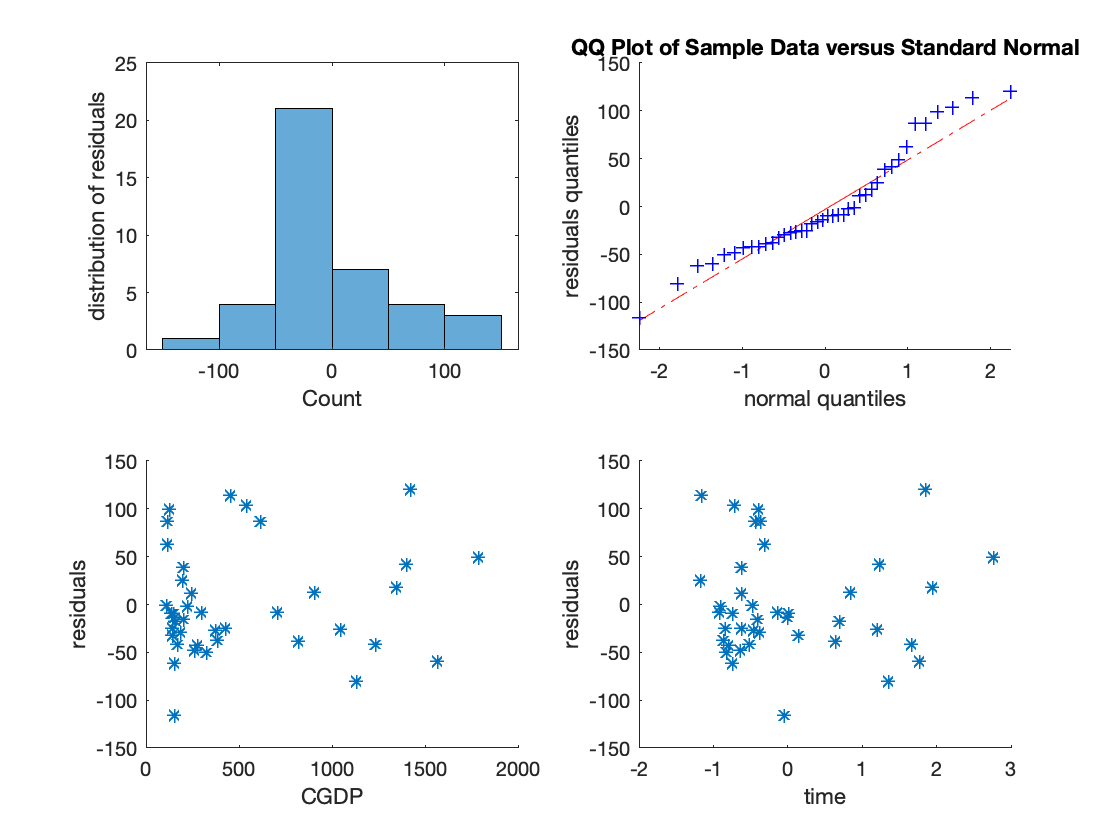

% plot residuals (ft at the end of this notebook)
plot_residuals(model_all,tr,y_tr);

In this plot, we do not see a clear pattern but we can still observe higher variability when CGDP grows (residuals are more concentrated around 0 when CGDP is low). Therefore, we suspect the homescedasticiy assumption not to be valid. Let's test that using a Breush Pagen Test. 

Breusch Pagan Test

[BP_stat,BP_crit,H] = Breusch_Pagan_test(tr,model_all.residuals,0.95);
H

H = 1

Thefore, we reject the homescedascity assumption. The next natural step would be to look at a more general version of least square where the homoscedasticity assumption is not required to be valid. FGLS constiute the alternative we are looking for. 

It is important to deal with this issue for  the following reasons: 

1) ordinary least squares no longer produces the unbiased/constistents estimators  

2) standard errors computed using least squares can be incorrect and misleading. 

FGLS

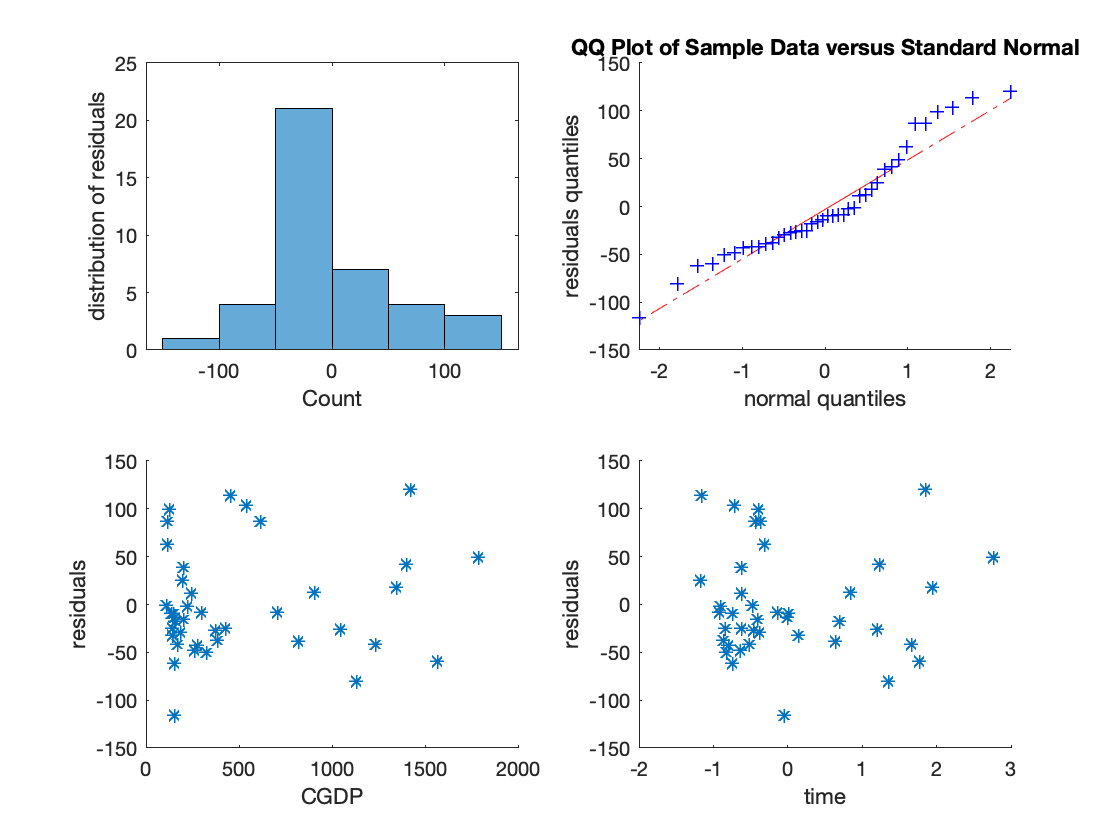

% FGLS fit
[model_FGLS,map_FGLS] = FGLS(tr,y_tr);
% map data into the space induced by FGLS operation
[ttr,ty_tr] = map_FGLS(tr,y_tr);
% Breush Pagan test on FGLS output
[BP_stat_FGLS,BP_crit_FGLS,H_FGLS] = Breusch_Pagan_test(ttr,model_FGLS.residuals,0.95);
plot_residuals(model_all,tr,y_tr);

H_FGLS

H_FGLS = 1

If we clearly see a drop in the value of the BP test but still, the FGLS is not powerfull enough to caputre all the heterscedasticity assumption in our dataset.

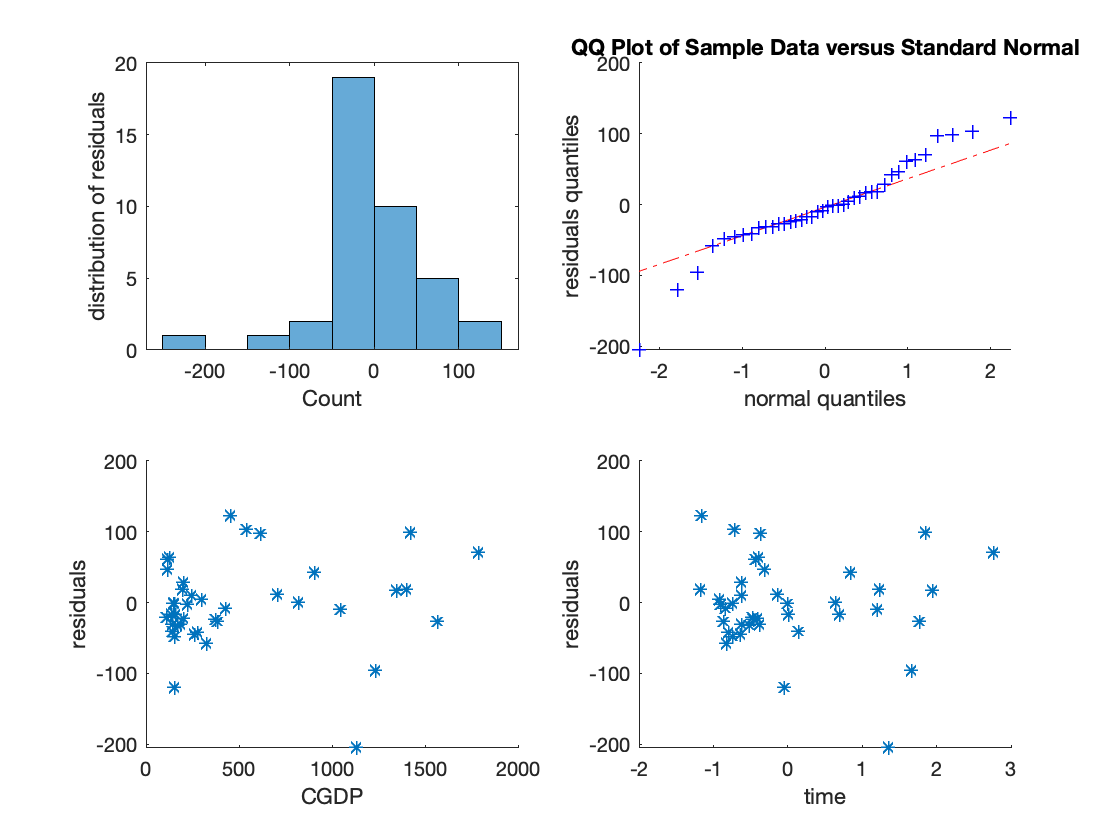

[model_FGLS_2,map_FGLS_2] = FGLS(tr,y_tr,"hetero");
[ttr_2,ty_tr_2] = map_FGLS_2(tr,y_tr);
[BP_stat_FGLS_2,BP_crit_FGLS_2,H_FGLS_2] = Breusch_Pagan_test(ttr_2,model_FGLS_2.residuals,0.95);
plot_residuals(model_FGLS_2,tr,y_tr);

H_FGLS_2

H_FGLS_2 = 1

## Transformations

We didn't manage to obtain satisfying results using FGLS methods thus we will try a different approach here. We will try to perform a least square on transformations of the inputs. By doing so we hope that impact of the residual heteroscedasticity will be reduced. 

% loglog tranformation : we transforme X and y by applying the log
loglog_model = ols(tr,y_tr,'loglog');

X and y have changed due to log log transformation !


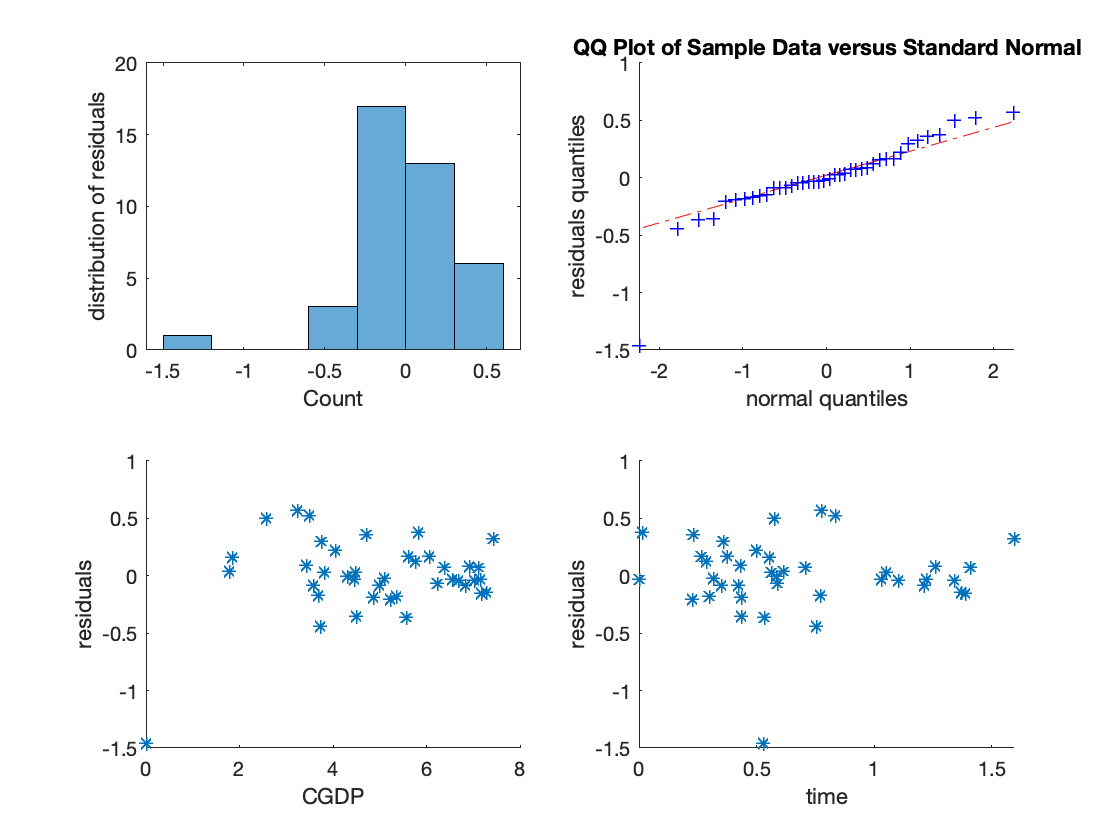

plot_residuals(loglog_model,loglog_model.tX,loglog_model.ty);

% R2 score on test set
%first we transform the test as using the same transformation as the train
%set 
transformed_te  = log_transform(te-min(tr)+1);
transformed_yte = log_transform(y_te-min(y_tr)+1);
% compute the statistics
[loglog_test_result] = test_model(loglog_model.beta,transformed_te,transformed_yte)

loglog_test_result = struct with fields:
                beta: [9×1 double]
              sigma2: 60.8602
          sample_var: [9×9 double]
           std_error: [9×1 double]
                 AIC: 3.6060
                 BIC: 3.8783
                  R2: -0.3164
              adj_R2: -10.8475
                  CI: [9×2 double]
            p_values: [9×1 double]
    significant_test: 0
           residuals: [10×1 double]
                pred: [10×1 double]
                 SSE: 60.8602


% Breusch pagan test
[BP_stat_FGLS_LOGLOG,BP_crit_FGLS_LOGLOG,H_FGLS_LOGLOG] = Breusch_Pagan_test(loglog_model.tX,loglog_model.residuals,0.95);
H_FGLS_LOGLOG

H_FGLS_LOGLOG = 1

% linlog tranformation : we transforme X  by applying the log
linlog_model= ols(tr,y_tr,'linlog');

X has changed due to log transformation


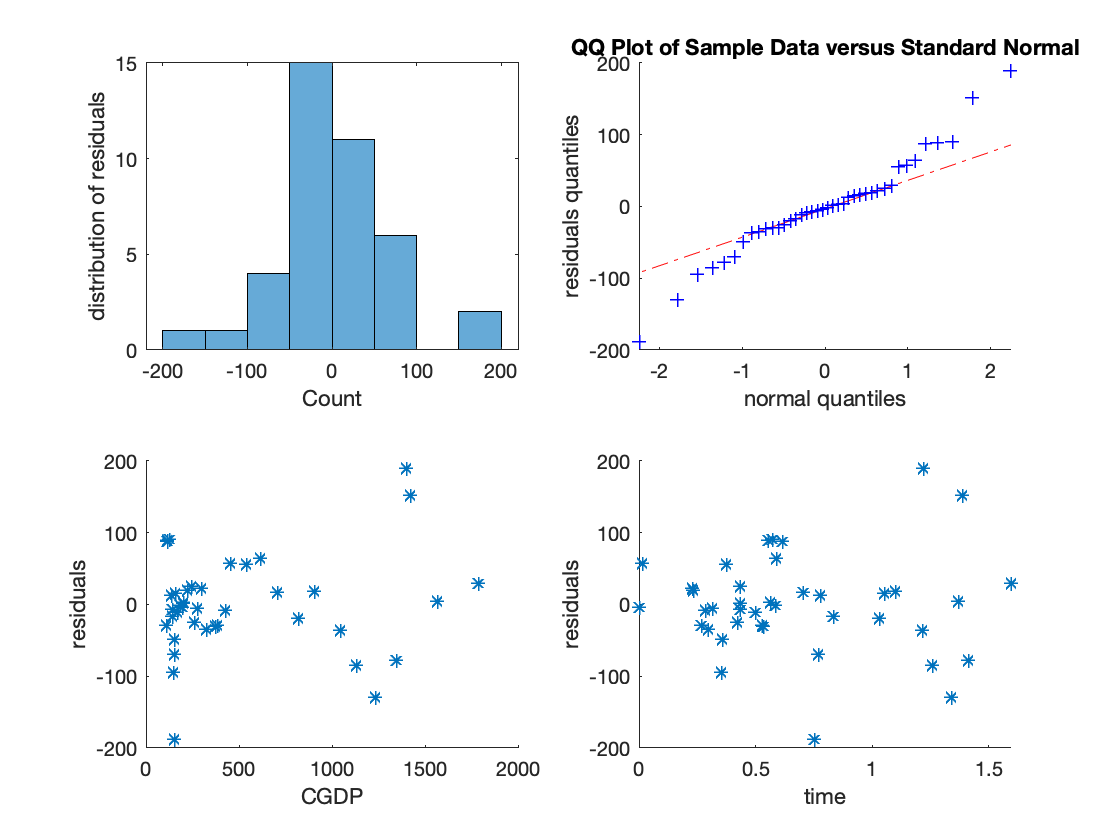

plot_residuals(linlog_model,linlog_model.tX,y_tr);

% R2 score on test set
[loglog_test_result] = test_model(linlog_model.beta,transformed_te,transformed_yte)

loglog_test_result = struct with fields:
                beta: [9×1 double]
              sigma2: 1.5914e+07
          sample_var: [9×9 double]
           std_error: [9×1 double]
                 AIC: 16.0801
                 BIC: 16.3524
                  R2: -3.4421e+05
              adj_R2: -3.0979e+06
                  CI: [9×2 double]
            p_values: [9×1 double]
    significant_test: 0
           residuals: [10×1 double]
                pred: [10×1 double]
                 SSE: 1.5914e+07


% Breusch pagan test
[BP_stat_FGLS_LINLOG,BP_crit_FGLS_LINLOG,H_FGLS_LINLOG] = Breusch_Pagan_test(linlog_model.tX,linlog_model.residuals,0.95);
H_FGLS_LINLOG

H_FGLS_LINLOG = 1

% loglin tranformation : we transforme y  by applying the log
loglin_model= ols(tr,y_tr,'loglin');

y has changed due to log transformation


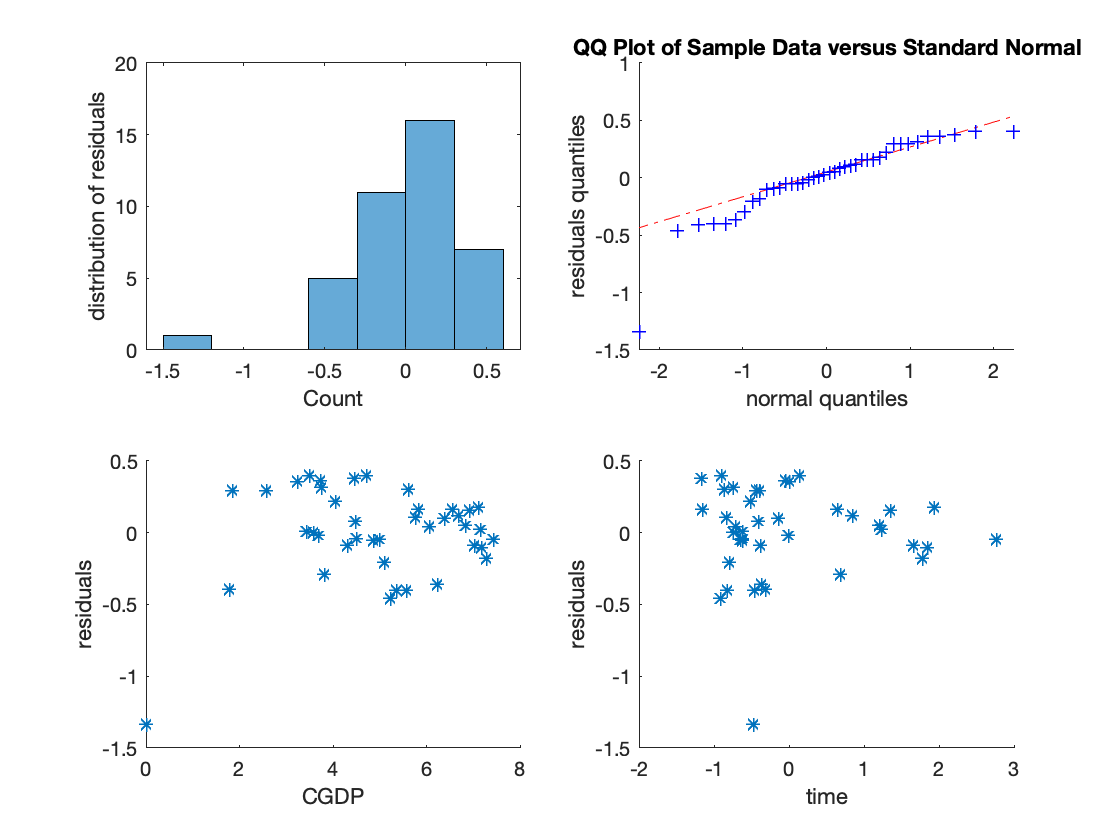

plot_residuals(loglin_model,tr,loglin_model.ty);

% R2 score on test set
[loglog_test_result] = test_model(loglin_model.beta,transformed_te,transformed_yte)

loglog_test_result = struct with fields:
                beta: [9×1 double]
              sigma2: 30.6436
          sample_var: [9×9 double]
           std_error: [9×1 double]
                 AIC: 2.9198
                 BIC: 3.1922
                  R2: 0.3372
              adj_R2: -4.9653
                  CI: [9×2 double]
            p_values: [9×1 double]
    significant_test: 0
           residuals: [10×1 double]
                pred: [10×1 double]
                 SSE: 30.6436


% Breusch pagan test
[BP_stat_LOGLIN,BP_crit_LOGLIN,H_LOGLIN] = Breusch_Pagan_test(tr,loglin_model.residuals,0.95);
H_FGLS_LINLOG

H_FGLS_LINLOG = 1

## Conclusion and Robust CI

Finally, since we were not able to have a good reduction of heteroscedasticity, we will just continue with our simple OLS estimator. However, we should provide robust standard errors in this case.

robust_CI_ols = robust_CI(tr,model_all);
robust_CI_ols

robust_CI_ols =     8.6421
   27.1834
   53.1235
   19.9466
   38.5734
   25.8246
   31.2157
   27.6928
   24.2210


## Helper Functions

function [] = plot_residuals(model,X,y)
    % ft used to plot residuals in 4 ways:
    % (a) Histogram 
    % (b) QQ plot with standard normal
    % (c) Scatter plot vs CGDP
    % (d) Scatter plot vs year
    figure;
    subplot(2,2,1);
    histogram(model.residuals);
    ylabel('distribution of residuals') ;
    xlabel('Count');
    subplot(2,2,2);
    qqplot(model.residuals);
    ylabel('residuals quantiles') ;
    xlabel('normal quantiles');
    subplot(2,2,3);
    scatter(y,model.residuals,'*');
    ylabel('residuals') ;
    xlabel('CGDP') ;
    subplot(2,2,4);
    scatter(X(:,2),model.residuals,'*');
    ylabel('residuals');
    xlabel('time') ;
end